clear;
clc;

In the baseline scenario: $\pi_s = 4.05 \times 10^{-7}$, $\eta = 10$, $\phi_1 = 0.2$

caseid  = 1;
parameters;
ups2    = 1 - ups1;
phi2    = (1 - phi1*ups1)/(1 - ups1);

Call Dynare:

dynare multisector noclearall;

Using 64-bit preprocessor
Starting Dynare (version 4.6.1).
Calling Dynare with arguments: noclearall
Starting preprocessing of the model file ...
Found 19 equation(s).
Evaluating expressions...done
Computing static model derivatives (order 1).
Computing dynamic model derivatives (order 1).
Processing outputs ...
done
Preprocessing completed.


STEADY-STATE RESULTS:

n          		 28.0056
c          		 1115.6
lambda_tau 		 41.4086
tau        		 0
I          		 0
T          		 0
S          		 1
R          		 0
D          		 0
C          		 0
C_sum      		 0
N          		 0
Ui         		 8263.51
Us         		 8304.96
Ur         		 8304.96
c1         		 557.802
c1_dev     		 0
c2         		 557.802
c2_dev     		 0
--------------------------------------------------------
MODEL SIMULATION :

Iter: 1,	 err. = 4.4956e-11, 	 time = 0.46277

Total time of simulation: 0.46572
--------------------------------------------------------

Perfect foresight solution found.

Total computing time : 0h00m0

Plot perfect foresight solutions:

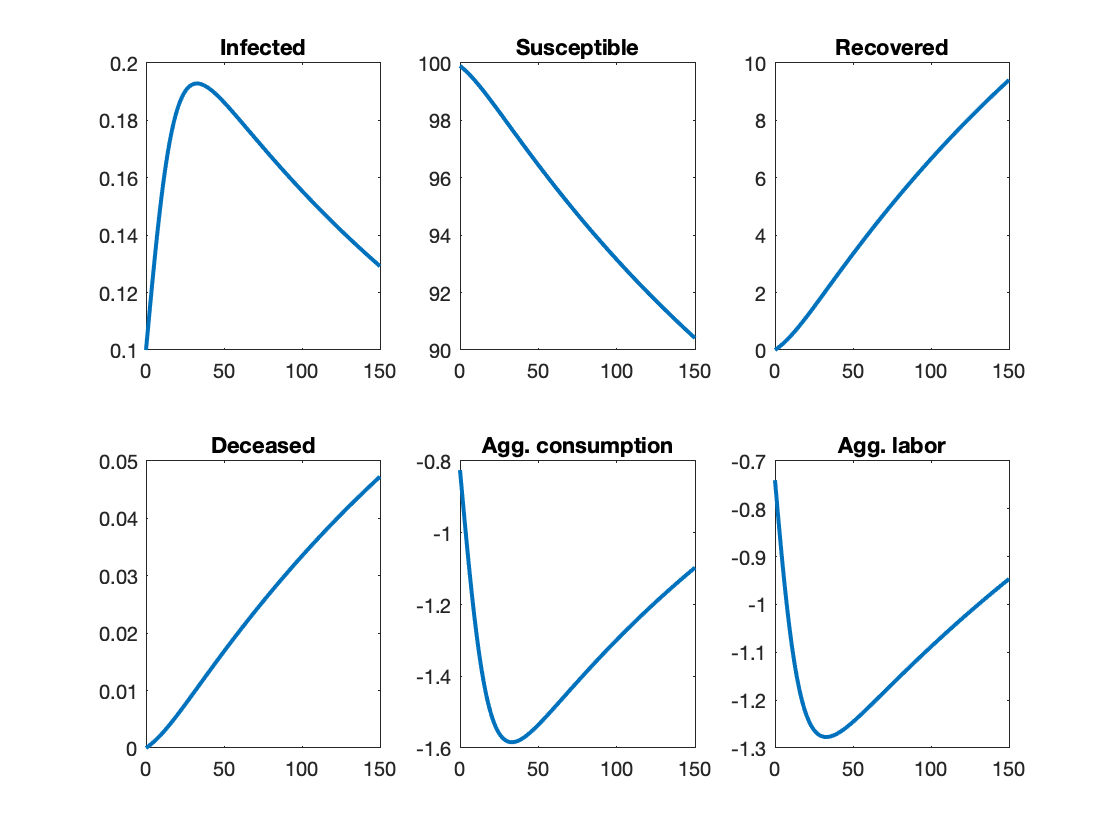

variables = [I S R D C N];
titles = {  'Infected',... 
            'Susceptible',...
            'Recovered',...
            'Deceased',...
            'Agg. consumption',...
            'Agg. labor'};
EndT = 150;
figure;
for n = 1:6
    subplot(2,3,n);
    plot(0:(0+EndT), 100*variables(2:(2+EndT),n), 'linewidth', 2);
    title(titles{n});
end